## Adjusted R-square of polyfit between Euclidean distance and IED XC delays

clc; clear; close all; 
addpath(fullfile('z_toolbox', 'Violinplot'));
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load(fullfile('step5_IEDxcorr_polyfit', 'IED6d0_XC100ms_polyfit_delay_Rmax_ED_as.mat'), 'adjR2_xcDED_as');
x = adjR2_xcDED_as(:, 6);
disp(mean(x)); disp(std(x));

    0.2567

    0.0202



figure('Units', 'centimeters', 'Position', [5, 5, 50, 30]);
subplot(2, 3, 1);
histogram(x, 30, 'FaceColor', [1, 0.5, 0.5], 'Normalization', 'probability');
xlabel('Adjusted R^2');
ylabel('Probability');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load(fullfile('step5_IEDxcorr_polyfit', 'IED6d0_XC100ms_polyfit_delays_Rmax_ED_es.mat'), 'adjR2_xcDED');
x = adjR2_xcDED(:, 6);
disp(mean(x)); disp(std(x));

    0.4788

    0.1609



for nS = 1:length(x)
    adjR2str{nS} = 'Euclidean Distance vs. IED-LC Delay';
end
subplot(2, 3, 4)
vs = violinplot(x, adjR2str, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'ViolinColor', [1, 0.5, 0.5; 0.5, 0.5, 1], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 16);
ylabel('Adjusted R^2');
xlim([0.5, 1.5]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## Sperman R of IED XC delays vs strength

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load(fullfile('step5_IEDxcorr_polyfit', 'IED6d0_XC100ms_polyfit_delay_Rmax_ED_as.mat'), ...
    'R_xcDR_as', 'R_xcDR_rED_as');
x = R_xcDR_as(:); y = R_xcDR_rED_as(:, 6);
disp(mean(x)); disp(std(x));

   -0.4607

    0.0084



disp(mean(y)); disp(std(y));

   -0.4344

    0.0088



subplot(2, 3, 2)
histogram(x, 30, 'FaceColor', [1, 0.5, 0.5], 'Normalization', 'probability');
hold on;
histogram(y, 30, 'FaceColor', [0.5, 0.5, 1], 'Normalization', 'probability');
hold off;
xlabel('Spearman Correlation');
ylabel('Probability');
ylim([0, 0.11]);
legend({'Unadjusted', 'Regress Distance'}, 'Box','off', 'Location', 'best');
set(gca, 'Box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load(fullfile('step5_IEDxcorr_polyfit', 'IED6d0_XC100ms_polyfit_delays_Rmax_ED_es.mat'), ...
    'R_xcDR', 'R_xcDR_rED');
x = R_xcDR(:); y = R_xcDR_rED(:, 6);
disp(mean(x)); disp(std(x));

   -0.5815

    0.1674



disp(mean(y)); disp(std(y));

   -0.5353

    0.1743



Rstr = {}; R = [];
for nS = 1:length(R_xcDR)
    Rstr{nS} = 'Unadjusted';
    Rstr{47+nS} = 'Regress Distance';
end
R(1:47) = x;
R(48:47*2) = y;
subplot(2, 3, 5);
vs = violinplot(R, Rstr, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Unadjusted', 'Regress Distance'}, ...
    'ViolinColor', [1, 0.5, 0.5; 0.5, 0.5, 1], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 16);
ylabel('Spearman Correlation');
xlim([0.5, 2.5]);
ylim([-0.96, -0.25]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## Spearman R of IED XC delays vs. fiber count

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load(fullfile('step5_IEDxcorr_polyfit', 'IED6d0_XC100ms_polyfit_delay_fibN.mat'), ...
    'R_fibNxcD_as', 'R_fibNxcD_rED_as');
x = R_fibNxcD_as(:); y = R_fibNxcD_rED_as(:, 6);
disp(mean(x)); disp(std(x));

   -0.2689

    0.0100



disp(mean(y)); disp(std(y));

   -0.0965

    0.0062



subplot(2, 3, 3);
histogram(x, 30, 'FaceColor', [1, 0.5, 0.5], 'Normalization', 'probability');
hold on;
histogram(y, 30, 'FaceColor', [0.5, 0.5, 1], 'Normalization', 'probability');
hold off;
xlabel('Spearman Correlation');
ylabel('Probability');
legend({'Unadjusted', 'Regress Distance'}, 'Box', 'off', 'Location', 'best');
set(gca, 'Box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load(fullfile('step5_IEDxcorr_polyfit', 'IED6d0_XC100ms_polyfit_delay_fibN.mat'), ...
    'R_fibNxcD', 'R_fibNxcD_rED');
R_fibNxcD(R_fibNxcD==0) = [];
R_fibNxcD_rED = R_fibNxcD_rED(:, 6);
R_fibNxcD_rED(R_fibNxcD_rED==0) = [];
x = R_fibNxcD; y = R_fibNxcD_rED;
disp(mean(x)); disp(std(x));

   -0.3059

    0.0748



disp(mean(y)); disp(std(y));

   -0.0883

    0.0715



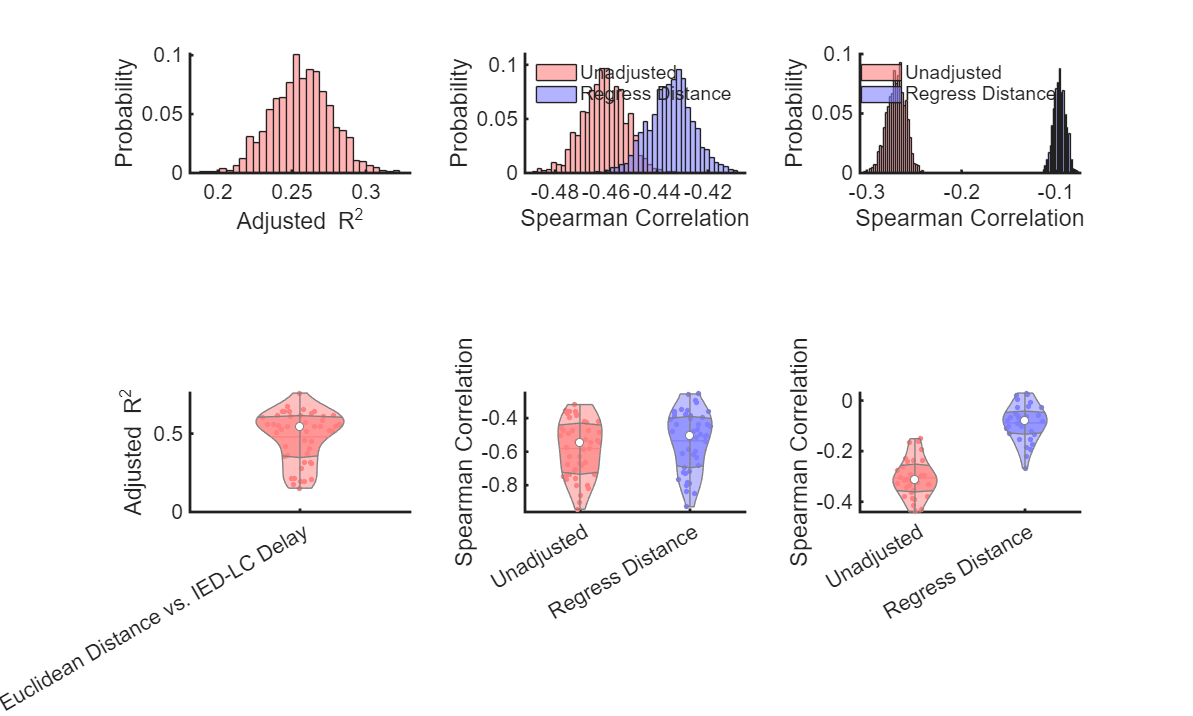

Rstr = {};
for nS = 1:length(R_fibNxcD)
    Rstr{nS} = 'Unadjusted';
Rstr{33+nS} = 'Regress Distance';
end
R = [];
R(1:33) = x;
R(34:33*2) = y;
subplot(2, 3, 6);
vs = violinplot(R, Rstr, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Unadjusted', 'Regress Distance'}, ...
    'ViolinColor', [1, 0.5, 0.5; 0.5, 0.5, 1], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 16);
ylabel('Spearman Correlation');
xlim([0.5, 2.5]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);